Initialization

clc;
clear;
img_org = imread("charact2.bmp");%read the original image

## 1.display the original image

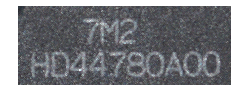

figure("Name","the original image");
imshow(img_org);

img_gray = rgb2gray(img_org);% transform to gray image

## 2.Implement 3x3 averaging mask and rotating mask.Try masks in other sizes

### 2.1 apply 3x3 averaging mask on the original image

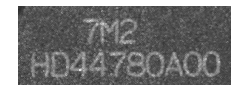

figure("Name","3x3 averaging mask image");
average_mask_3by3 = ones(3,3)./9;                       % create the mask
img_3by3average = imfilter(img_gray,average_mask_3by3);  % apply the mask
imshow(img_3by3average);                                % display the 3x3 averaged image

### 2.2 apply 3x3 rotating mask on the original image

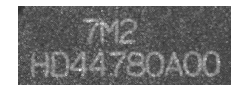

img_3by3rotate = img_gray;%initialize 3x3 rotating masked image
for i = 3:365
    for j = 3:988
        dispersion = 0;
        dispersion_min = 0;
        for k = -1:1
            for l = -1:1
                %calculate dispersion
                dispersion = 1 / 9 * (img_gray(i,j) - mean(mean(img_gray(i+k-1:i+k+1,j+l-1:j+l+1)))) ^ 2;
                if dispersion <= dispersion_min
                    dispersion_min = dispersion;
                    img_3by3rotate(i,j) = mean(mean(img_gray(i+k-1:i+k+1,j+l-1:j+l+1)));
                end
            end
        end
    end
end
imshow(img_3by3rotate);